# Homework 2

## Harley Hanes

## 9/17/19

## Problem 1


$$$A =\left[
\begin{array}{cc}
2 & -1 \\
-1 & 2 \\
\end{array}\right]$$$


To find  $U^{T}AU=\Lambda$ we first find the eigenvalues of A by solving $det(A-\lambda I)=0$.


$$$0=det\left(
\left[
\begin{array}{cc}
2 & -1 \\
-1 & 2 \\
\end{array}\right]-\lambda
\left[
\begin{array}{cc}
1 & 0 \\
0 & 1 \\
\end{array} \right]
\right)=
\left(\left[
\begin{array}{cc}
2-\lambda & -1\\
-1 & 2-\lambda\\
\end{array}
\right]\right)\\
0=(2-\lambda)^2-1=
\lambda^2-4\lambda+3=(\lambda-3)(\lambda-1)\\
\rightarrow \lambda=1,3$$


Next we find the eigenvectors corresponding to each eigenvalue,

$\lambda=1$:


$$$A =\left[
\begin{array}{cc}
2 & -1 \\
-1 & 2 \\
\end{array}\right]
\left[
\begin{array}{c}
v_1 \\
v_2 \\
\end{array}\right]=
\left[
\begin{array}{c}
 v_1 \\
v_2 \\
\end{array}\right] \rightarrow
\left\{ \begin{array}{cc}
2v_1 -v_2&= v_1 \\
-v_1 + 2v_2&=v_2\\
\end{array}
\rightarrow
v_1=v_2$$$


$\lambda=3$:


$$$A =\left[
\begin{array}{cc}
2 & -1 \\
-1 & 2 \\
\end{array}\right]
\left[
\begin{array}{c}
v_1 \\
v_2 \\
\end{array}\right]=
\left[
\begin{array}{c}
3v_1 \\
3v_2 \\
\end{array}\right] \rightarrow
\left\{ \begin{array}{cc}
2v_1 -v_2&= 3v_1 \\
-v_1 + 2v_2&=3v_2\\
\end{array}
\rightarrow
v_1=-v_2$$$


From this we find,

$U=\frac{1}{\sqrt{2}}\left[\begin{array}{cc} 1 & 1 \\ -1 & 1\end{array}\right]$, $$\Lambda=\left[\begin{array}{cc} 3 & 0 \\ 0 & 1\end{array}\right]$$

such that $U^{T}AU=\Lambda$

## Problem 5

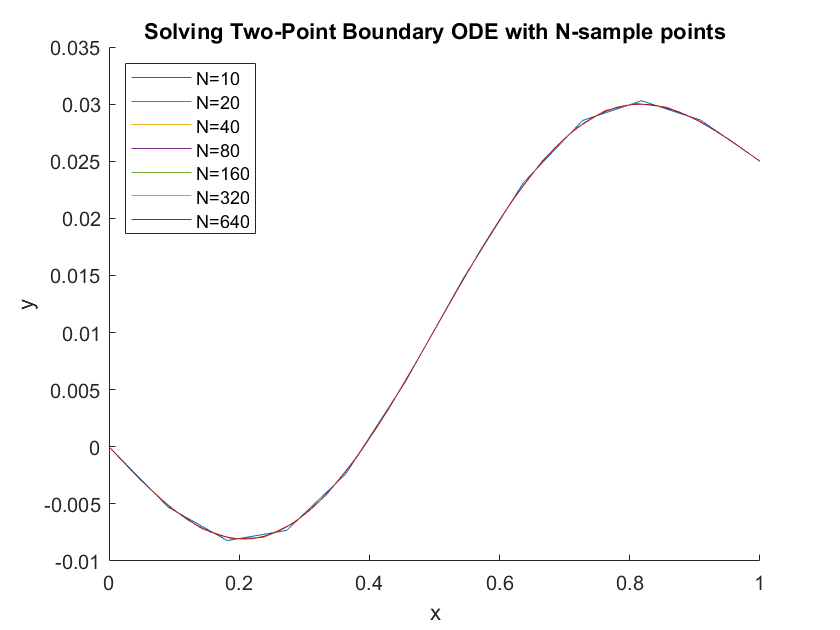

figure
hold on
for N=[10, 20, 40, 80, 160, 320, 640]
    t=linspace(0,1,N+2);
    x=t(2:length(t)-1);
    % Define Problem
    h=1/(N+1);
    p=@(x) 1 + exp(-(x-.5)^2);
    r=@(x) .2 * exp(-x);
    q=@(x) 4;
    f=@(x) sin(2*pi*x);
    yl=0;
    yr=.025;
    % Define A and b
    A=NaN(N);
    b=NaN(N,1);
    A(1,:)=[-(2 * p(x(1)) + h^2 * q(x(1))),...
        p(x(1)) + h/2 * r(x(1)),...
        zeros(1,N-2)];
    b(1)=h^2 * f(x(1)) - yl * (p(x(1)) - h/2 * r(x(1)));
    for i=2:N-1
        A(i,:)=[zeros(1,i-2),...
            p(x(i)) - h/2 * r(x(i)),...        %Column i-1
            -(2 * p(x(i)) + h^2 * q(x(i))),... %Column i
            p(x(i)) + h/2 * r(x(i)),...        %Column i+1
            zeros(1,N-(i+1))];
        b(i)=h^2 * f(x(i));
    end
    A(N,:)=[zeros(1,N-2),...
        p(x(N)) - h/2 * r(x(N)),...
        -(2 * p(x(N)) + h^2 * q(x(N)))];
    b(N)=h^2 * f(x(N)) - yr * (p(x(N)) + h/2 * r(x(N)));
    %LU Decomp
    [L,U]=LUDecomp(A);
    %Solve Lower Triangular
    Yl=LowerSolve(L,b);
    %Solve Upper Triangular
    Y=UpperSolve(U,Yl);
    Yplot=[yl;Y;yr];
    plot(t,Yplot)
end
legend({'N=10','N=20','N=40', 'N=80', 'N=160', 'N=320', 'N=640'},'location','northwest')
title('Solving Two-Point Boundary ODE with N-sample points')
xlabel('x')
ylabel('y')

## Problem 2

function [L,U] = LUDecomp(A)
sizecheck=size(A);
if sizecheck(1)~=sizecheck(2)
    fprintf("Error!! Entered matrix is not square")
    keyboard
end
n=sizecheck(1);
U=zeros(n);
L=zeros(n);

for i=1:n
    for k=i:n
        U(i,k)=A(i,k)-L(i,:)*U(:,k);
    end
    for k=i:n
        if i==k
            L(k,k)=1;
        else
            L(k,i)=(A(k,i)-L(k,:)*U(:,i))/U(i,i);
        end
    end
end
end

## Problem 3

function xU = UpperSolve(U,b)
sizecheck=size(U);
if sizecheck(1)~=sizecheck(2)
    fprintf("Error!! Entered matrix is not square")
    keyboard
end
n=sizecheck(1);
xU=NaN(size(b));
for i=n:-1:1
    if i==n
        xU(i)=b(i)/U(i,i);
    else
        j=n:-1:i+1;
        xU(i)=(b(i)-U(i,j)*xU(j))/U(i,i);
    end
end
end

## Problem 4

function xL = LowerSolve(L,b)
sizecheck=size(L);
if sizecheck(1)~=sizecheck(2)
    fprintf("Error!! Entered matrix is not square")
    keyboard
end
n=sizecheck(1);
xL=NaN(size(b));
for i=1:n
    if i==1
        xL(i)=b(i)/L(i,i);
    else
        j=1:i-1;
        xL(i)=(b(i)-L(i,j)*xL(j))/L(i,i);
    end
end
end